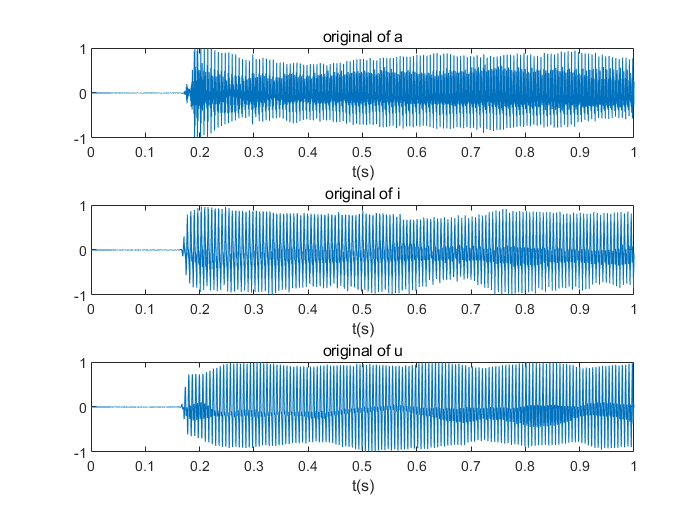

%sample with 16000Hz

% recorder=audiorecorder(16000,16,1);
% %记录/a/
% disp('start recording');
% recordblocking(recorder,1);
% disp('end recording');
% a=getaudiodata(recorder);
% filename='a.wav';
% audiowrite(filename,a,16000);
% 
% %记录/i/
% disp('start recording');
% recordblocking(recorder,1);
% disp('end recording');
% i=getaudiodata(recorder);
% filename='i.wav';
% audiowrite(filename,i,16000);
% 
% %记录/u/
% disp('start recording');
% recordblocking(recorder,1);
% disp('end recording');
% u=getaudiodata(recorder);
% filename='u.wav';
% audiowrite(filename,u,16000);

[a,fsa]=audioread('a.wav');
[i,fsi]=audioread('i.wav');
[u,fsu]=audioread('u.wav');
figure
subplot(3,1,1);
ta=0:1/fsa:(length(a)-1)/fsa;
plot(ta,a);
xlabel('t(s)');
title('original of a');
subplot(3,1,2);
ti=0:1/fsi:(length(i)-1)/fsi;
plot(ti,i);
xlabel('t(s)');
title('original of i');
subplot(3,1,3);
tu=0:1/fsu:(length(u)-1)/fsu;
plot(tu,u);
xlabel('t(s)');
title('original of u');

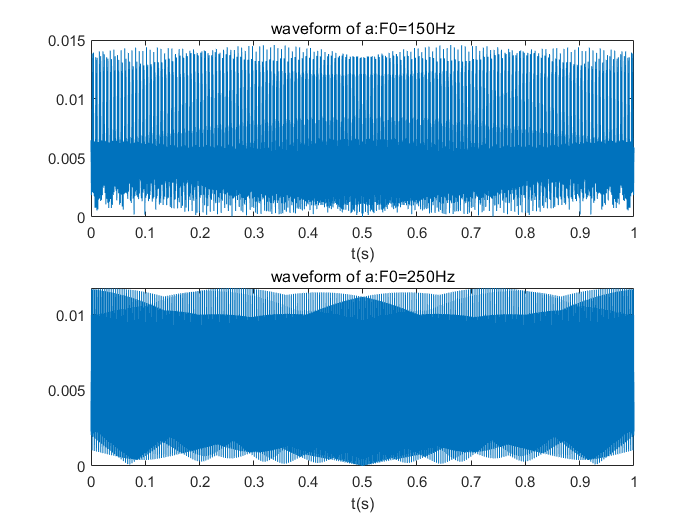


%use pure-tones to synthesize

a_f=fftshift(fft(a));
na=length(a_f);
Malea=zeros(1,na/2);
Malea(150:150:na/2)=a_f(na/2+150:150:na);
Malea_f=[flip(Malea),Malea];
Malea_t=abs(ifft(ifftshift(Malea_f)));
Femalea=zeros(1,na/2);
Femalea(250:250:na/2)=a_f(na/2+250:250:na);
Femalea_f=[flip(Femalea),Femalea];
Femalea_t=abs(ifft(ifftshift(Femalea_f)));

i_f=fftshift(fft(i));
ni=length(i_f);
Malei=zeros(1,ni/2);
Malei(150:150:ni/2)=i_f(ni/2+150:150:ni);
Malei_f=[flip(Malei),Malei];
Malei_t=abs(ifft(ifftshift(Malei_f)));
Femalei=zeros(1,ni/2);
Femalei(250:250:ni/2)=a_f(ni/2+250:250:ni);
Femalei_f=[flip(Femalei),Femalei];
Femalei_t=abs(ifft(ifftshift(Femalei_f)));

u_f=fftshift(fft(u));
nu=length(u_f);
Maleu=zeros(1,nu/2);
Maleu(150:150:nu/2)=a_f(nu/2+150:150:nu);
Maleu_f=[flip(Maleu),Maleu];
Maleu_t=abs(ifft(ifftshift(Maleu_f)));
Femaleu=zeros(1,nu/2);
Femaleu(250:250:nu/2)=a_f(nu/2+250:250:nu);
Femaleu_f=[flip(Femaleu),Femaleu];
Femaleu_t=abs(ifft(ifftshift(Femaleu_f)));

%plot waveforms
figure
subplot(2,1,1);
t_Malea=0:1/fsa:(length(Malea_t)-1)/fsa;
plot(t_Malea,Malea_t);
xlabel('t(s)');
title('waveform of a:F0=150Hz');
subplot(2,1,2);
t_Femalea=0:1/fsa:(length(Femalea_t)-1)/fsa;
plot(t_Femalea,Femalea_t);
xlabel('t(s)');
title('waveform of a:F0=250Hz');

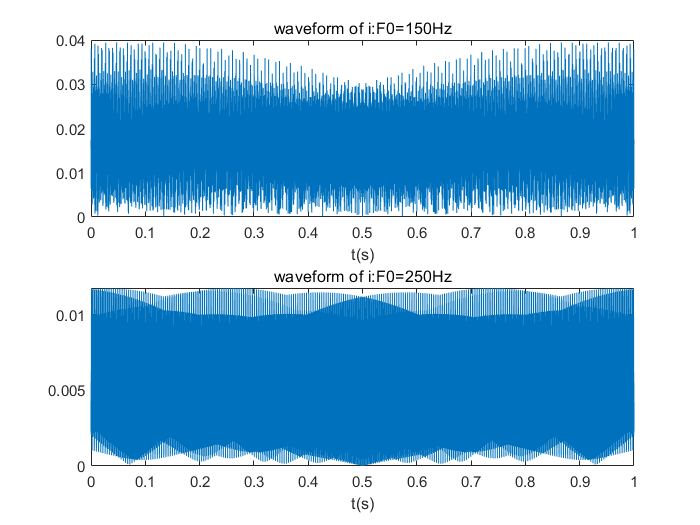


figure
subplot(2,1,1);
t_Malei=0:1/fsi:(length(Malei_t)-1)/fsi;
plot(t_Malei,Malei_t);
xlabel('t(s)');
title('waveform of i:F0=150Hz');
subplot(2,1,2);
t_Femalei=0:1/fsi:(length(Femalei_t)-1)/fsi;
plot(t_Femalei,Femalei_t);
xlabel('t(s)');
title('waveform of i:F0=250Hz');

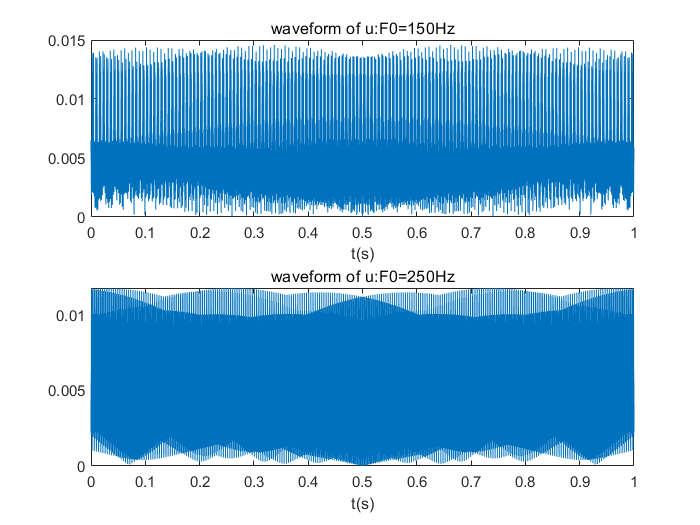


figure
subplot(2,1,1);
t_Maleu=0:1/fsu:(length(Maleu_t)-1)/fsu;
plot(t_Maleu,Maleu_t);
xlabel('t(s)');
title('waveform of u:F0=150Hz');
subplot(2,1,2);
t_Femaleu=0:1/fsu:(length(Femaleu_t)-1)/fsu;
plot(t_Femaleu,Femaleu_t);
xlabel('t(s)');
title('waveform of u:F0=250Hz');

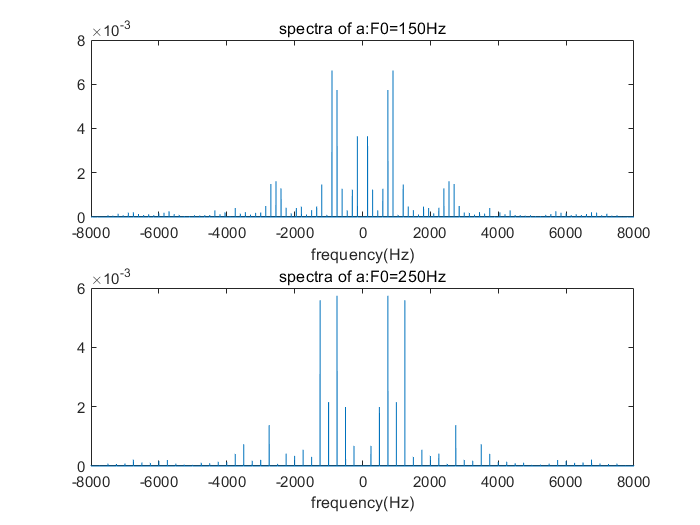


%plot spectra
figure
subplot(2,1,1);
f_Malea=(-na/2:1:na/2-1)*(fsa/na);
plot(f_Malea,abs(Malea_f)*2/length(Malea_f));
xlabel('frequency(Hz)');
title('spectra of a:F0=150Hz');
subplot(2,1,2);
f_Femalea=(-na/2:1:na/2-1)*(fsa/na);
plot(f_Femalea,abs(Femalea_f)*2/length(Femalea_f));
xlabel('frequency(Hz)');
title('spectra of a:F0=250Hz');

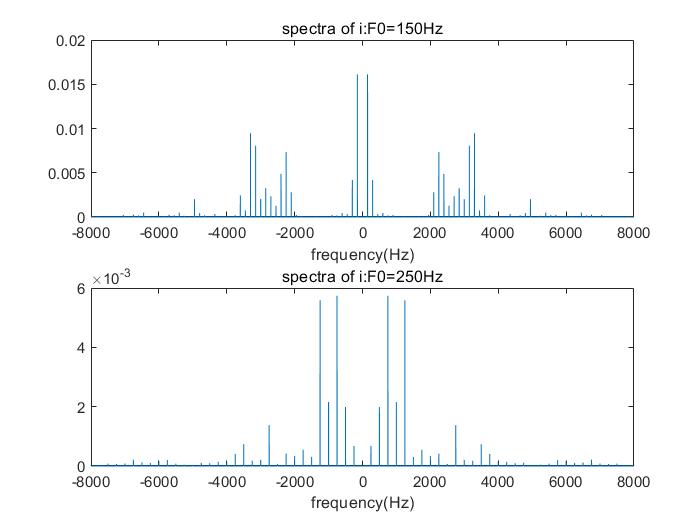


figure
subplot(2,1,1);
f_Malei=(-ni/2:1:ni/2-1)*(fsi/ni);
plot(f_Malei,abs(Malei_f)*2/length(Malei_f));
xlabel('frequency(Hz)');
title('spectra of i:F0=150Hz');
subplot(2,1,2);
f_Femalei=(-ni/2:1:ni/2-1)*(fsi/ni);
plot(f_Femalei,abs(Femalei_f)*2/length(Femalei_f));
xlabel('frequency(Hz)');
title('spectra of i:F0=250Hz');

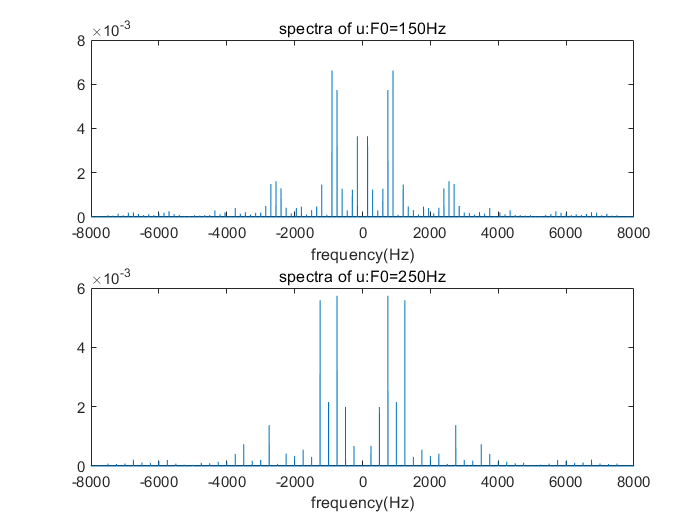


figure
subplot(2,1,1);
f_Maleu=(-nu/2:1:nu/2-1)*(fsu/nu);
plot(f_Maleu,abs(Maleu_f)*2/length(Maleu_f));
xlabel('frequency(Hz)');
title('spectra of u:F0=150Hz');
subplot(2,1,2);
f_Femaleu=(-nu/2:1:nu/2-1)*(fsu/nu);
plot(f_Femaleu,abs(Femaleu_f)*2/length(Femaleu_f));
xlabel('frequency(Hz)');
title('spectra of u:F0=250Hz');

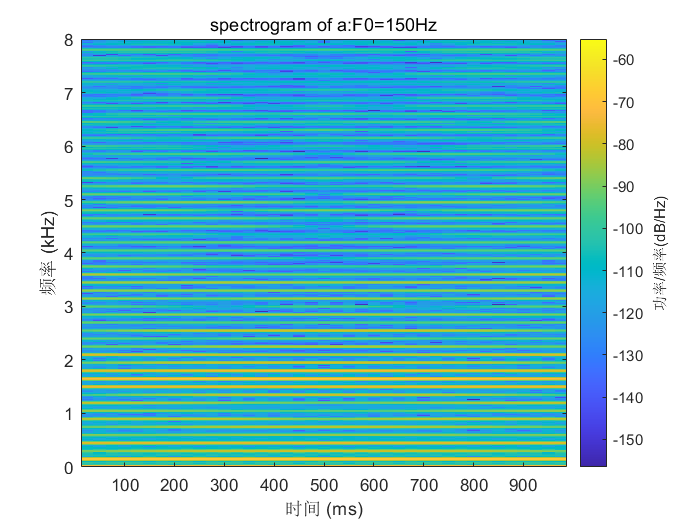


%plot spectrogram
figure;
spectrogram(Malea_t,800,[],fsa,fsa,'yaxis');
title('spectrogram of a:F0=150Hz');

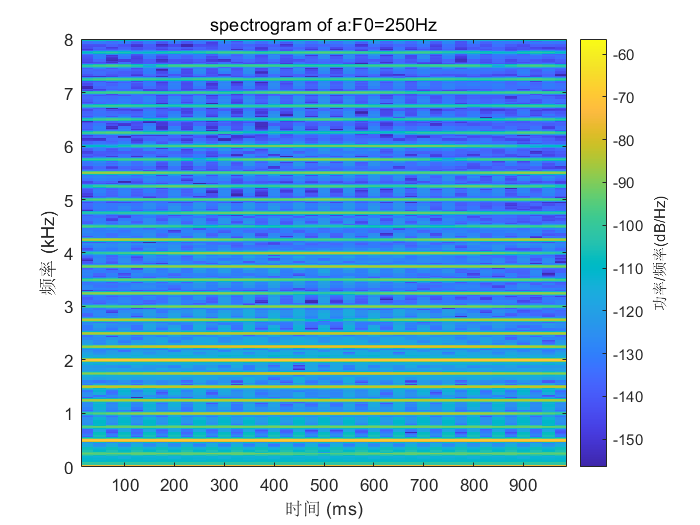

figure;
spectrogram(Femalea_t,800,[],fsa,fsa,'yaxis');
title('spectrogram of a:F0=250Hz');

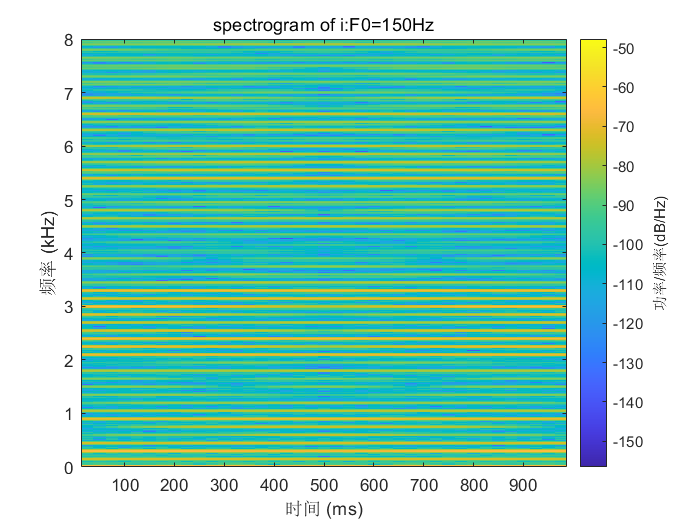

figure;
spectrogram(Malei_t,800,[],fsi,fsi,'yaxis');
title('spectrogram of i:F0=150Hz');

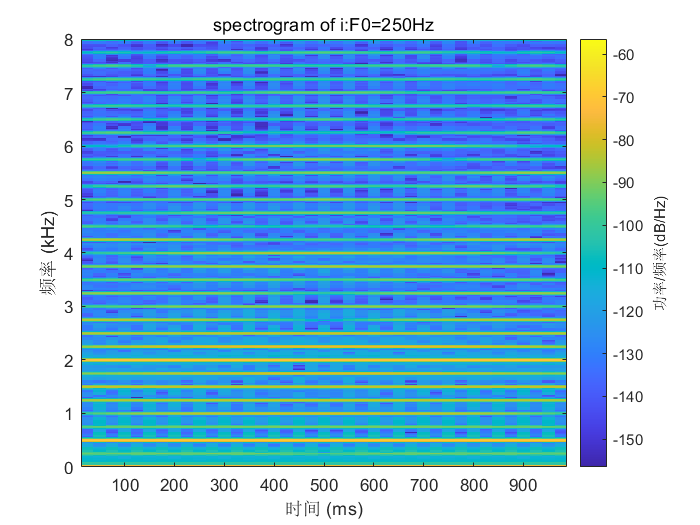

figure;
spectrogram(Femalei_t,800,[],fsi,fsi,'yaxis');
title('spectrogram of i:F0=250Hz');

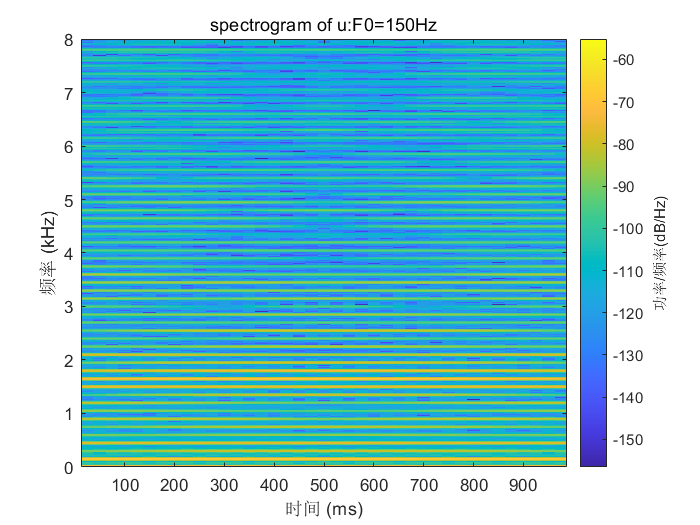

figure;
spectrogram(Maleu_t,800,[],fsu,fsu,'yaxis');
title('spectrogram of u:F0=150Hz');

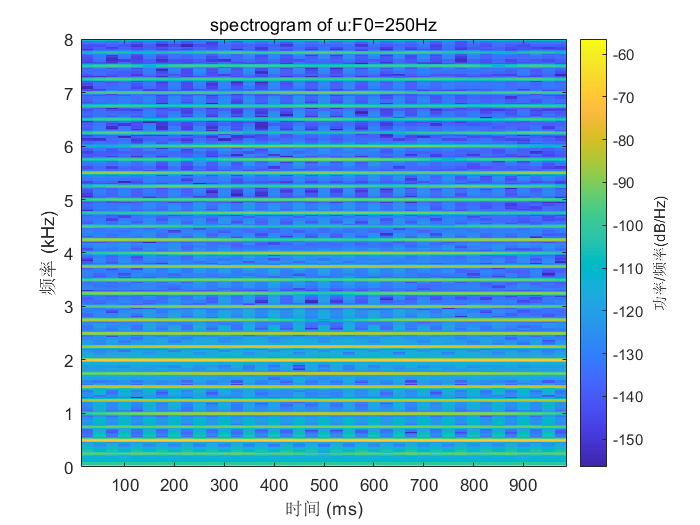

figure;
spectrogram(Femaleu_t,800,[],fsu,fsu,'yaxis');
title('spectrogram of u:F0=250Hz');


%attach the wav file
audiowrite('a_150.wav',Malea_t,fsa);
audiowrite('a_250.wav',Femalea_t,fsa);
audiowrite('i_150.wav',Malei_t,fsi);
audiowrite('i_250.wav',Femalei_t,fsi);
audiowrite('u_150.wav',Maleu_t,fsu);
audiowrite('u_250.wav',Femaleu_t,fsu);



